# Laboratorio 8 Control Discreto - Discreto

k=0.7867;
tao=0.64;

tm=4*tao/50

tm = 0.0512

888888
plantaContinua=tf(k,[tao 1])

plantaContinua =
 
    0.7867
  ----------
  0.64 s + 1
 
Continuous-time transfer function.



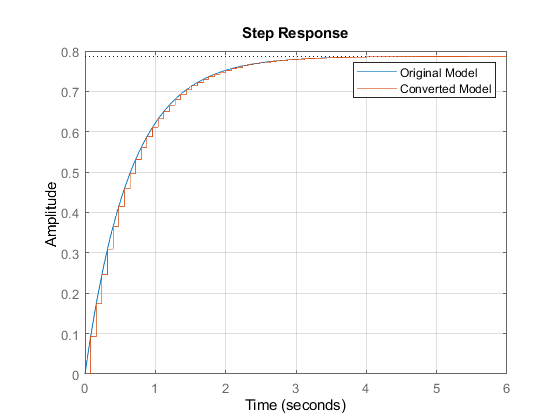

% Convert model from continuous to discrete time
plantaDis = c2d(plantaContinua,0.08);

% Visualize the results
stepplot(plantaContinua,plantaDis);
legend('Original Model','Converted Model');
grid on;

plantaDis

plantaDis =
 
   0.09244
  ----------
  z - 0.8825
 
Sample time: 0.08 seconds
Discrete-time transfer function.



[B,A]=tfdata(plantaDis,'v')

B =          0    0.0924


A =     1.0000   -0.8825



syms r0 r1 r2 z

B=poly2sym(B,z)

$$B = \frac{6660981419866273}{72057594037927936}$$

A=poly2sym(A,z)

$$A = z-\frac{3974412721635601}{4503599627370496}$$

R=r0*z^2+r1*z+r2;
S=collect((z-1)*(z-1),z)

$$S = z^{2}-2\,z+1$$


% polinomio deseado

zd=0.9;
tsd=4;
wnd=4/(zd*tsd)

wnd = 1.1111

p1=-2*exp(-zd*wnd*tm)...
    *cos(wnd*tm*sqrt(1-zd^2));
p2= exp(-2*zd*wnd*tm);

poldes=vpa(collect((z^2+p1*z+p2)*(z-0.1),z),4)

$$poldes = z^{3}-2.0\,z^{2}+1.093\,z-0.09027$$


polcarac=vpa(collect(B*R+A*S,z),4)

$$polcarac = z^{3}+\left(0.09244\,r_{0}-2.882\right)\,z^{2}+\left(0.09244\,r_{1}+2.765\right)\,z+0.09244\,r_{2}-0.8825$$


sol=vpa(coeffs(polcarac,z)==coeffs(poldes,z),4)

$$sol = \left(\begin{array}{cccc} 0.09244\,r_{2}-0.8825=-0.09027 & 0.09244\,r_{1}+2.765=1.093 & 0.09244\,r_{0}-2.882=-2.0 & 1.0=1.0 \end{array}\right)$$

sol=solve(sol)

sol = struct with fields:
    r0: [1×1 sym]
    r1: [1×1 sym]
    r2: [1×1 sym]



r0=double(sol.r0)

r0 = 9.5511

r1=double(sol.r1)

r1 = -18.0914

r2=double(sol.r2)

r2 = 8.5702


[B,A]=tfdata(plantaDis,'v') 

B =          0    0.0924


A =     1.0000   -0.8825
